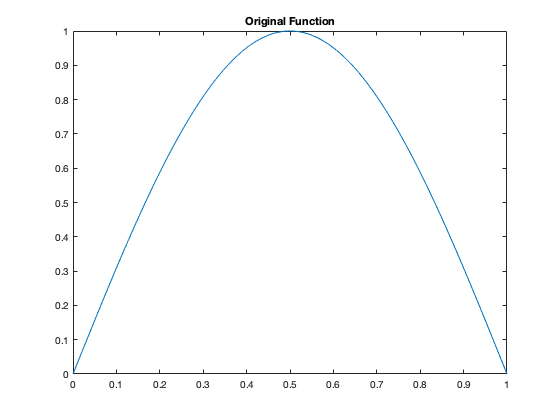

clc; clear; close all;

k = 0.00125; % step size
L = 1; % end of original domain
C = 200; % continuation points

phi = @(x) sin(pi*x/L); % function
D = transpose(0:k:L); % domain
phi_D = phi(D); % function values on domain
figure;
plot(D, phi_D);
title("Original Function")


% Interpolation Procedure
d = 10; % degree of interpolation
D_l = D(1:d); % left side of mesh on domain of function
D_r = D(end-d+1:end); % right side of mesh on domain of function
phi_D_l = phi(D_l); % phi values on left side of mesh
phi_D_r = phi(D_r); % phi values on right side of mesh

D_C = transpose(L+k:k:L+C*k); % vector of only continuation points domain
D_l_C = D_l + D_C(end) + k; % left side of mesh of next periods domain after continuation, has values of phi_D_l

D_interpolant = [D_r;D_l_C]; % mesh used for interpolation
mu_D = mean(D_interpolant);
std_D = std(D_interpolant);
D_hat_interpolant = (D_interpolant - mu_D)./std_D; % scaling interpolation mesh for better stability
D_C_hat = (D_C - mu_D)./std_D;

phi_interpolant = [phi_D_r; phi_D_l]; % function values used for interpolation
w = barycentric_weights(D_hat_interpolant) % barycentric weights dependent on interpolation mesh

w =      2.016147027466700e-02
    -1.901352053175404e-01
     7.971052838311746e-01
    -1.949763166086384e+00
     3.066617795203968e+00
    -3.216208907165114e+00
     2.249244137690522e+00
    -1.011447574936086e+00
     2.653798092654331e-01
    -3.095364276119832e-02


phi_C_num = barycentric_compute_func(w, D_hat_interpolant, phi_interpolant, D_C_hat); % continuation values using barycentric interpolation

[poly_C, ~, mu] = polyfit(D_interpolant, phi_interpolant, length(D_interpolant)-1);

phi_C = polyval(poly_C, D_C, [], mu); %matlab interpolation
disp(phi_C - phi_C_num)

     6.043776590303196e-15
     6.096512183972891e-14
     3.167119344560376e-13
     1.109556890810381e-12
     3.415486643509880e-12
     8.329722328559441e-12
     2.273274971043016e-11
     4.809910109093707e-11
     8.063659462376194e-11
     1.951024619639696e-10
     3.107489751630332e-10
     5.817963402710014e-10
     8.450368252366225e-10
     1.269072388843107e-09
     2.041758720428000e-09
     3.074293444815801e-09
     5.377819869978318e-09
     7.010656333239496e-09
     1.130570631557859e-08
     1.592919669779480e-08
     2.314407898662552e-08
     2.829800009596095e-08
     5.095340598060272e-08
     4.594055839912681e-08
     6.930144111350067e-08
     8.729789482964101e-08
     1.550085935719814e-07
     1.819326321955694e-07
     1.724807636160897e-07
     2.361127633826454e-07
     3.371086502862441e-07
     4.216036507131982e-07
     4.247646123167748e-07
     6.960860928217905e-07
     1.104506277632700e-06
     1.036541085269738e-06
     1.069378935153464e-06
 

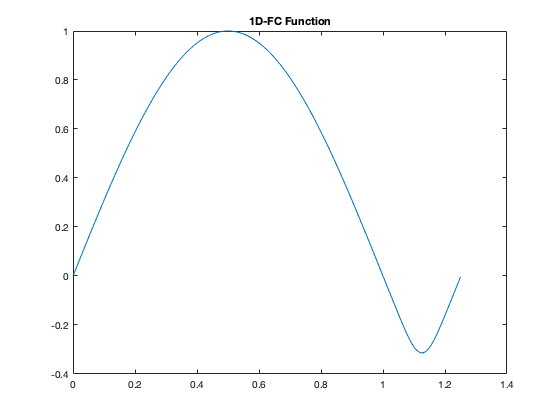


D_FC = [D; D_C]; % final continued domain
phi_FC = [phi_D; phi_C]; % final continued function values
figure;
plot(D_FC, phi_FC)
title("1D-FC Function")

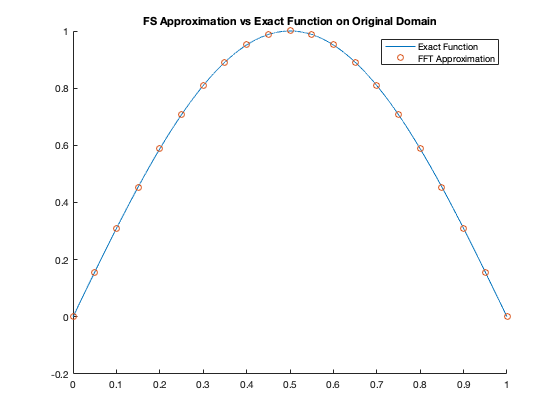


% FFT Procedure
L_FC = D_FC(end) + k; % new period after 1D-FC
C_n = FFT_coeff(phi_FC); % ceofficients given by FFT

% Error Calculation
k_err = k/20;
D_err = transpose(0:k_err:L);
phi_FFT = FFT_compute_func(C_n, L_FC, D_err);
phi_exact = phi(D_err);

figure;
hold on;
plot(D_err, phi_exact)
plot(transpose(0:0.05:1), FFT_compute_func(C_n, L_FC, transpose(0:0.05:1)), 'o')
title("FS Approximation vs Exact Function on Original Domain")
legend('Exact Function', 'FFT Approximation')


err = max(abs(phi_FFT - phi_exact)) % max error on mesh

err =      3.330669073875470e-15
